nice publication quality figures

**Exemplar trajectories**

rng('default');%initialize RNG for reproducibility

%choose params which support stable tug of war, ie
% high native processivity, low PG unbinding rate eps0<< koff0
% frequent PG binding, pi0>> kOn0
% otherwise based on experimental data rates

motorState.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorState.pi0 =10*motorState.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorState.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration 
% derived from Stu data)
%processivity is synthesis limited
motorState.kOff0 = 10*motorState.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)
motorState.Fdetach = 1;%detachment force pN nm
motorState.Fstall = 100; %stall force pN nM
motorState.vF=40;%forward velocity nm/s
motorState.vB=0.1;%backward velocity nm/s

motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;
simPar.doFixedTime=true;
simPar.simTime = 2000;

**Nmax=1**

%Nmax = 1 each side (max number of motors), low concentration, which should give frequent pausing model
motorState.Nmax = 1;


**Low concentration**

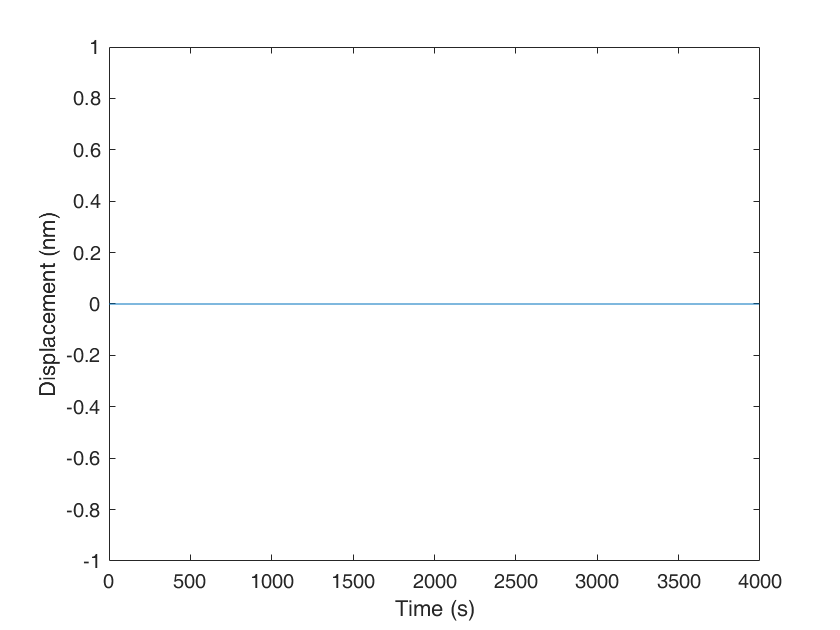

motorState.motorConcentration =1e-2;%arb units, essentiall scaling of low synthase concentration data here

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

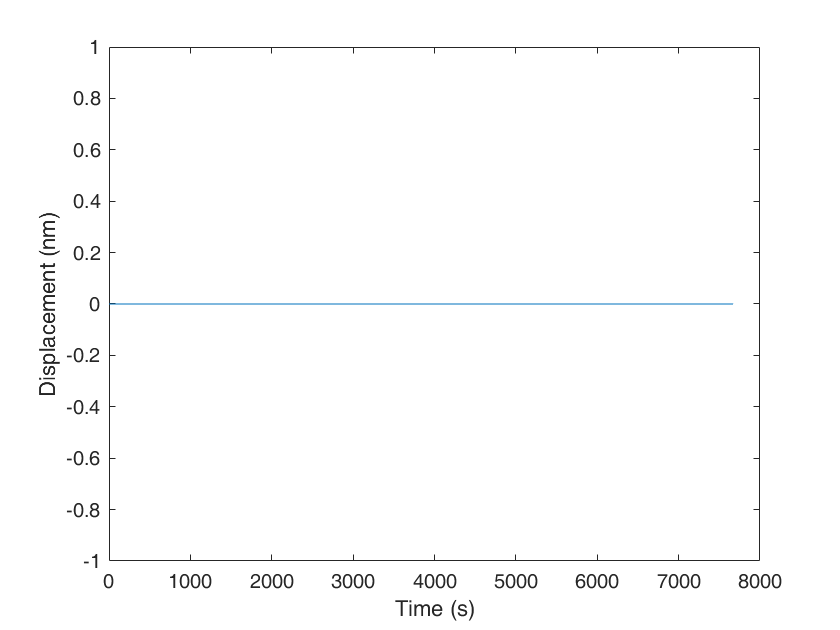

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

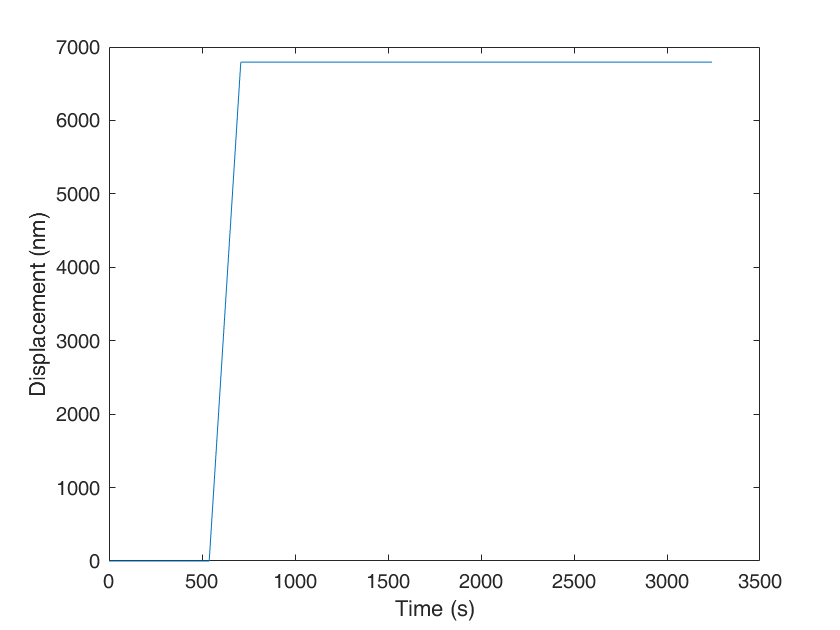

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

**Intermediate concentration**

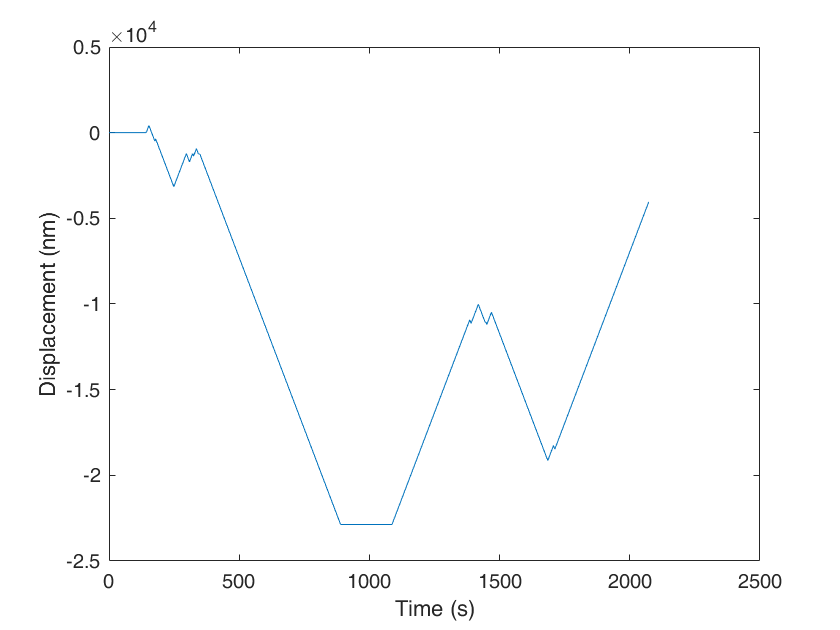

motorState.motorConcentration =1e0;%arb units, essentiall scaling of low synthase concentration data here

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

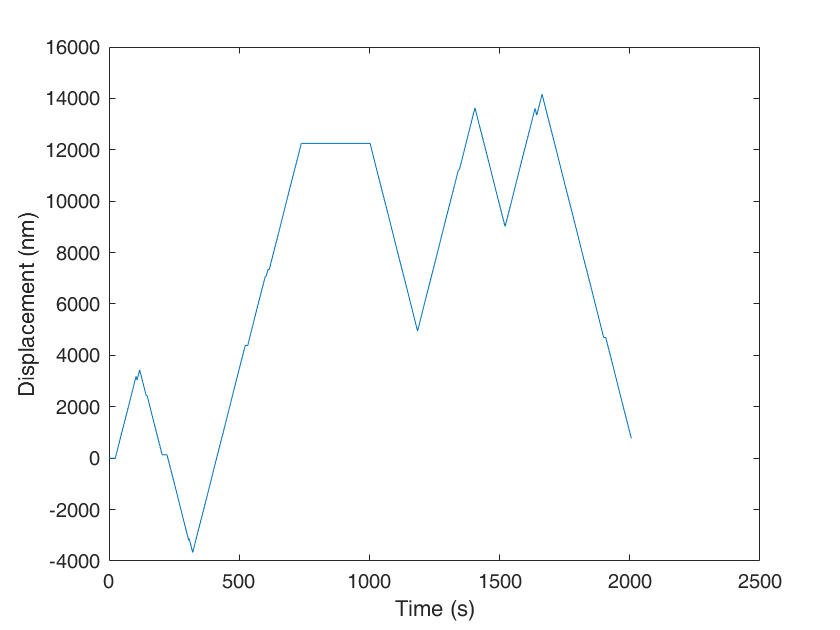

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

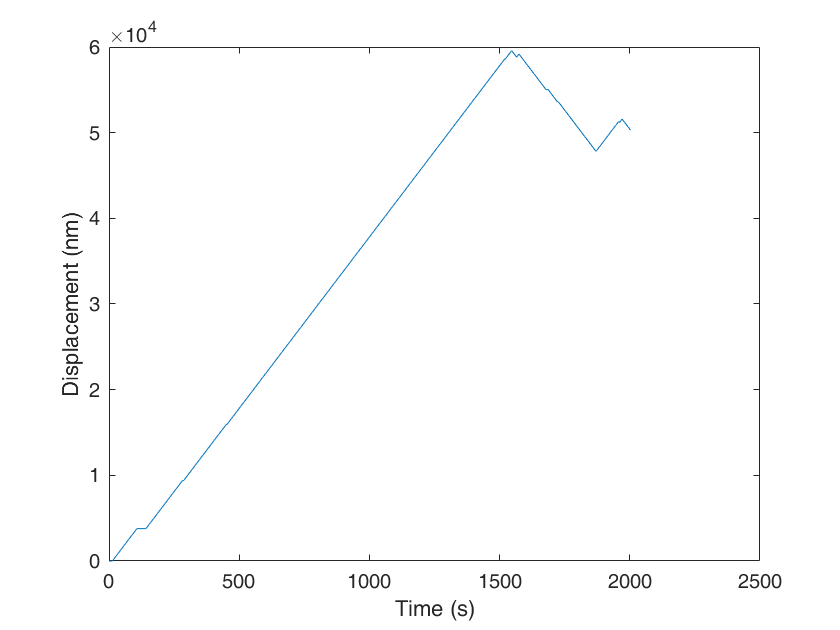

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

**High concentration**

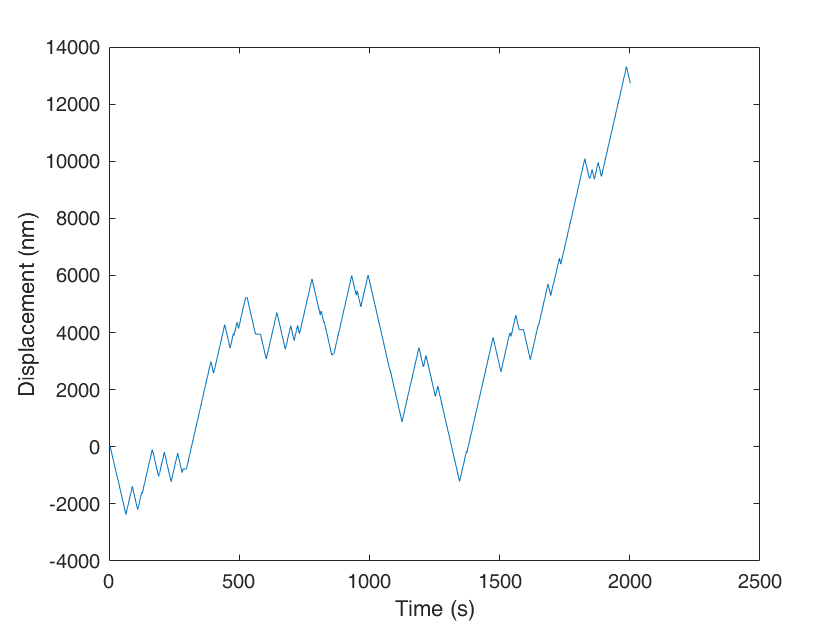

motorState.motorConcentration =1e2;%arb units, essentiall scaling of low synthase concentration data here

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

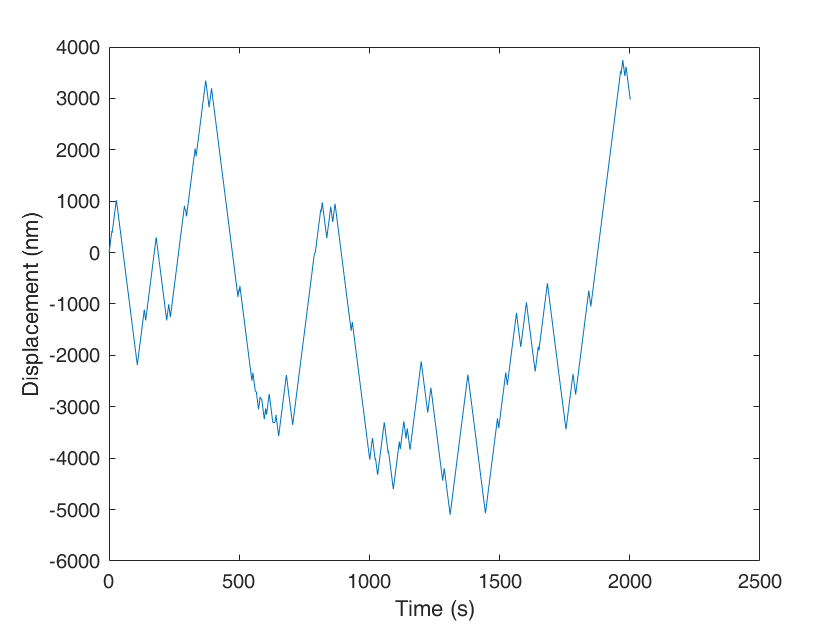

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

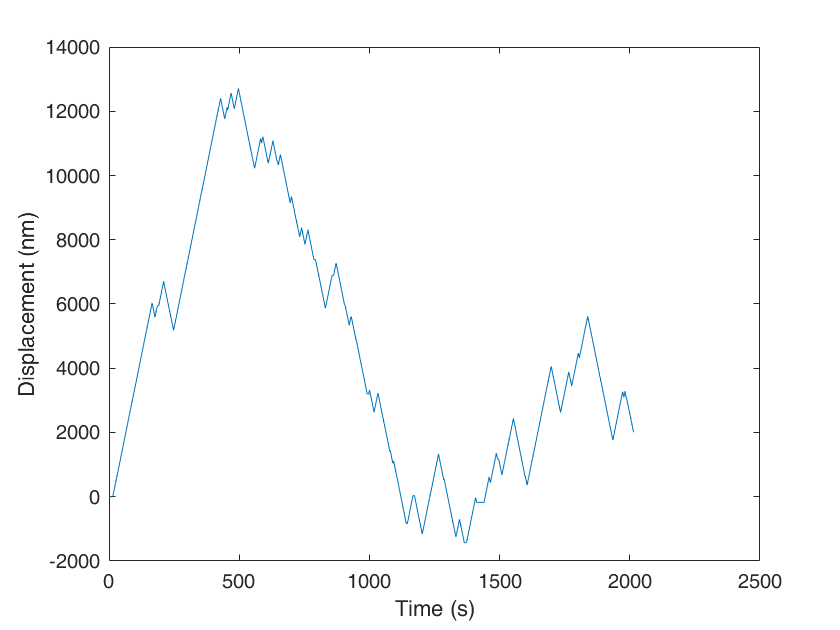

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');